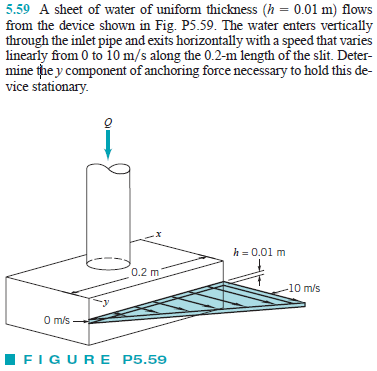

# given

u = symunit;
w = 0.2*u.m;
h = 0.01*u.m;
rho = 999*u.kg/u.m^3;

# inflow properties

syms Q;
mdot1(Q) = rho*Q;

# outflow properties

syms x;
V2(x) = findpoly(1, 'thru', [0 0], [w 10*u.m/u.s]);
mdot2 = rho*int(V2*h, [0 w]);

# conservation of mass

Q = solve(mdot1 == mdot2);

# conservation of momentum (y-direction)

Fy = rewrite(int(V2*rho*V2*h, [0 w]), u.N);
Fy_vpa = vpa(Fy) %#ok

$$Fy\_vpa = 66.6\,N$$

clear Fy_vpa;